This is a workbook to attempt to find a mixed effects model for the pilot data collected from Qualtrics for the EEE study. 

By Ben Graul

master = readtable('https://raw.githubusercontent.com/ben-g-1/Psyc178/main/pilot_clean.csv');
master.Pair = categorical(master.Pair);
master.Image = categorical(master.Image);
master.subj = categorical(master.subj);
master.highcue_indx = categorical(master.highcue_indx);

master = 7872×45 table
    subj    group    trial    highcue_indx    img_rate    exp_rate    val_type    cue_observed_std    cue_value_1    cue_value_2    cue_value_3    cue_value_4    cue_value_5    cue_value_6    cue_value_7    cue_value_8    cue_value_9    cue_value_10    cue_deviation_from_norm    cue_observed_mean    Image           Theme             Category     Pair    Half           Source           Valence_mean    Valence_SD    Valence_N    Arousal_mean    Arousal_SD</

master.val_type = categorical(master.val_type);

master = 7872×45 table
    subj    group    trial    highcue_indx    img_rate    exp_rate    val_type    cue_observed_std    cue_value_1    cue_value_2    cue_value_3    cue_value_4    cue_value_5    cue_value_6    cue_value_7    cue_value_8    cue_value_9    cue_value_10    cue_deviation_from_norm    cue_observed_mean    Image           Theme             Category     Pair    Half           Source           Valence_mean    Valence_SD    Valence_N    Arousal_mean    Arousal_SD</

master.Half = categorical(master.Half);

master = 7872×45 table
    subj    group    trial    highcue_indx    img_rate    exp_rate    val_type    cue_observed_std    cue_value_1    cue_value_2    cue_value_3    cue_value_4    cue_value_5    cue_value_6    cue_value_7    cue_value_8    cue_value_9    cue_value_10    cue_deviation_from_norm    cue_observed_mean    Image           Theme             Category     Pair    Half           Source           Valence_mean    Valence_SD    Valence_N    Arousal_mean    Arousal_SD</

master.group = categorical(master.group);

master = 7872×45 table
    subj    group    trial    highcue_indx    img_rate    exp_rate    val_type    cue_observed_std    cue_value_1    cue_value_2    cue_value_3    cue_value_4    cue_value_5    cue_value_6    cue_value_7    cue_value_8    cue_value_9    cue_value_10    cue_deviation_from_norm    cue_observed_mean    Image           Theme             Category     Pair    Half           Source           Valence_mean    Valence_SD    Valence_N    Arousal_mean    Arousal_SD</

What do the data look like? We care about the rating that participants gave to an image after seeing a cue type. 

hicue_val = (master.img_rate(master.highcue_indx == 1));

Error using  == 
Comparison is not defined between categorical and double arrays.

locue_val = (master.img_rate(master.highcue_indx == -1));

highmean = mean(hicue_val);
lowmean = mean(locue_val);
[h,p,ci,stats] = ttest(hicue_val, locue_val)

figure; hold on; 
swarmchart(master.highcue_indx, master.img_rate)
xlabel(['Low Cue', 'High Cue'])

% Add mean line for comparison
%Clean up violin 

hold off;

cues = [hicue_val, locue_val];
% figure; 
% violinplot_canlab(cues, 'xlabel', {'High Cue', 'Low Cue'}, 'mc', 'k')

Let's start off with a very simple regression for predicting the valence score from the normative OASIS valence ratings.

We'll include a positive control for something that should have no relationship with the ratings for a sanity check.  

lme1 = fitlme(master, 'img_rate ~ Valence_mean')

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69206    69227    -34600           69200   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.1575       0.58831    -8.7665    7870    2.2311e-18    -6.3107    -4.0042
    {'Valence_mean'}         1.0393     0.0097856     106.21    7870             0     1.0202     1.0585

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        19.617    

badlme = fitlme(master, 'img_rate ~ Half')

badlme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Half

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    76205    76226    -38099           76199   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue     Lower      Upper 
    {'(Intercept)'}         51.932      1.0906      47.62    7870          0     49.794     54.07
    {'Half'       }        0.54345     0.68973    0.78791    7870    0.43077    -0.8086    1.8955

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        30.598      30.124    31.079


 It looks like there's a strong connection between these subject valence ratings and the OASIS valence ratings. This is not surprising. 

What if we add in the variable of interest? 

lme2 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx');
compare(lme1, lme2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme1     3     69206    69227    -34600                               
    lme2     4     69118    69146    -34555    89.77     1          0     


This produces a significant improvement.  

Can we improve by adding subjects as a random effect? 

lme3 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1|subj)');
compare(lme2, lme3, 'CheckNesting', true)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme2     4     69118    69146    -34555                               
    lme3     5     68754    68789    -34372    365.94    1          0     


This was also a significant improvement. 

What about if we cross the effect instead?

lme4 = fitlme(master, 'img_rate ~ Valence_mean * highcue_indx + (1|subj)');
compare(lme3, lme4, 'CheckNesting', true) %Not significant

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme3     5     68754    68789    -34372                                 
    lme4     6     68756    68798    -34372    0.24535    1          0.62037


Doesn't seem to have any real benefit. Let's try to account for individual preference of a given image *within* each subject.

lme5 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1 + Image|subj)');
compare(lme3, lme5, 'CheckNesting', true) %sig 

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue   
    lme3     5     68754    68789    -34372                                  
    lme5     7     68748    68797    -34367    10.646    2          0.0048773



lme5 = fitlme(master, 'img_rate ~ Valence_mean * highcue_indx + (highcue_indx|subj) + (1 | Image)');
compare(lme3, lme5, 'CheckNesting', true) %sig

lme5 = fitlme(master, 'img_rate ~ Valence_mean * highcue_indx + (highcue_indx|subj) + (1 | Pair/Image)');
compare(lme3, lme5, 'CheckNesting', true) %sig

So currently, what we're seeing is that the normative valence rating provided with the OASIS set **and** the type of cue provided for a given image both impact the valence rating the participants give. 

Furthermore, a random effect ***crossing each image with each subject*** to estimate personal preference of a given image explains more of the data than just adding the subjects as a random effect. 

Can we see if the *category of cue type* or the *actual average observed in the cue* matter more?

lme6 = fitlme(master, 'img_rate ~ Valence_mean + cue_observed_mean + (1 + Image|subj)');
compare(lme5, lme6, 'CheckNesting', false) % p = 0?

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lme5     7     68748    68797    -34367                                
    lme6     7     68750    68799    -34368    -2.4975    0          0     


This confused me, because the AIC and BIC are both higher for #6, but the p value is 0. I think this might mean that it can't compute the difference. Let's keep #5 moving forward. 

Another thing we should consider is that while each subject will see the same images, a given image is randomly assigned to be higher or lower than the normative mean. Does accounting for this improve our model?

lme7 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1 + Image|subj) + (1 + highcue_indx|Image)');
compare(lme5, lme7, 'CheckNesting', true) % p = 0 again.

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme5      7    68748    68797    -34367                               
    lme7     10    68231    68300    -34105    523.09    3          0     


We had hypothesized that paired images would be rated similarly within subjects. Is this true?

lme8 = fitlme(master, 'img_rate ~ Valence_mean + cue_observed_mean + (1 + Pair|subj) +  (1 + highcue_indx|Image)');

% lme8 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1 + Image|subj) + (1 + highcue_indx|Pair)')
compare(lme8, lme7, 'CheckNesting', false) % p = 0; 5 is still best

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme8     10    68239    68309    -34110                               
    lme7     10    68231    68300    -34105    8.5042    0          0     


The `image pair x subj` interaction was not a significant improvement. That's a bit disappointing, and makes me wonder if the image pairs will actually be that helpful for comparisons. 


bestlme = lme5

bestlme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        246
    Covariance parameters                4

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + (1 + Image | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68748    68797    -34367           68734   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.6694      0.72138    -7.8591    7869    4.3833e-15    -7.0835    -4.2553
    {'highcue_indx'}         2.0892      0.21151     9.8779    7869     7.051e-23     1.6746     2.5039
    {'Valence_mean'}         1.0393     0.009361     111.03    7869             0      1.021     1.0577

Random effects 

What does this look like right now?

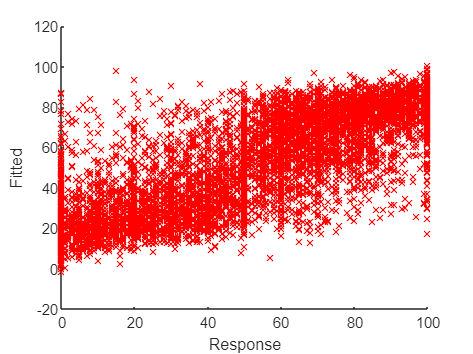

F = fitted(bestlme);
R = response(bestlme);
figure(); hold on;
plot(R,F,'rx')
xlabel('Response')
ylabel('Fitted')
hold off; 

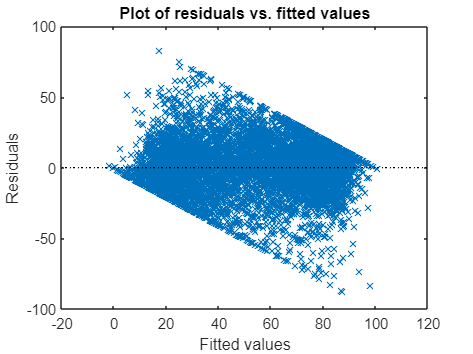


figure();
plotResiduals(bestlme, 'fitted')

Do we care about the ratings, or do we actually care about the *difference between *pairs of ratings?

Let's create a table focused on within-pair comparisons

master = sortrows(master,"Pair","ascend");

cuehl = master.highcue_indx;
cuemean = master.cue_observed_mean;
pair = master.Pair;
rating = master.img_rate;
stimmean = master.Valence_mean;

wh_high = cuehl > 0;
wh_low = cuehl < 0;

hi_table = master(wh_high, :);
lo_table = master(wh_low, :);

pair_table = table();
pair_table.subj = hi_table.subj;
pair_table.Pair = hi_table.Pair;
pair_table.group = hi_table.group

pair_table = 3936×3 table
    subj    Pair    group
    ____    ____    _____

      3      1        1  
      5      1        1  
      9      1        1  
     14      1        1  
     17      1        1  
     22      1        1  
     27      1        1  
     28      1        1  
     33      1        1  
     34      1        1  
     37      1        1  
     40      1        1  
     46      1        1  
     48      1        1  
     56      1        1  
     59      1        1  


pair_table.hi_val = hi_table.img_rate;
pair_table.lo_val = lo_table.img_rate;
pair_table.rating_mean = (hi_table.img_rate + lo_table.img_rate)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.img_rate - lo_table. img_rate;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
pair_table.norm_hi = pair_table.hi_val - pair_table.rating_mean;
pair_table.norm_lo = pair_table.lo_val - pair_table.rating_mean;


What do these data look like?

[h,p,ci,stats] = ttest(pair_table.rating_diff)

h = 1

p = 9.7374e-48

ci =     3.6268
    4.7421


stats = struct with fields:
    tstat: 14.7124
       df: 3935
       sd: 17.8436


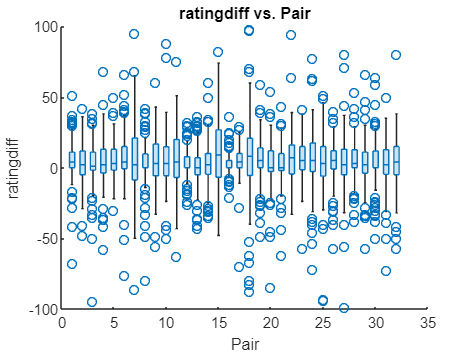


% Create boxchart of pair_table.Pair and pair_table.rating_diff
h1 = boxchart(pair_table.Pair,pair_table.rating_diff,"DisplayName","rating_diff");

% Add xlabel, ylabel, title, and legend
xlabel("Pair")
ylabel("ratingdiff")
title("ratingdiff vs. Pair")

It seems like outliers might be really messing this up.'

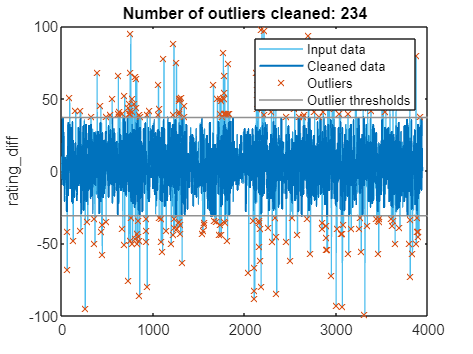

% Remove outliers
[cleanpairs,outlierIndices,~,thresholdLow,thresholdHigh] = rmoutliers(pair_table,...
    "percentiles",[3 97],"DataVariables","rating_diff");

% Display results
figure
plot(pair_table.rating_diff,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(find(~outlierIndices),cleanpairs.rating_diff,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),pair_table.rating_diff(outlierIndices),"x",...
    "Color",[217 83 25]/255,"DisplayName","Outliers")

% Plot outlier thresholds
plot([xlim missing xlim],...
    [thresholdLow.rating_diff*[1 1] NaN thresholdHigh.rating_diff*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
ylabel("rating_diff","Interpreter","none")

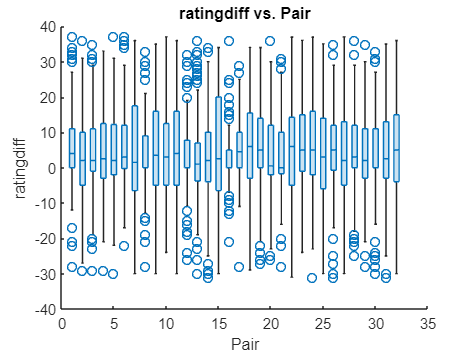

clear thresholdLow thresholdHigh

% Create boxchart of pair_table.Pair and pair_table.rating_diff
h2 = boxchart(cleanpairs.Pair, cleanpairs.rating_diff,"DisplayName","rating_diff");

% Add xlabel, ylabel, title, and legend
xlabel("Pair")
ylabel("ratingdiff")
title("ratingdiff vs. Pair")


[h,p,ci,stats] = ttest(cleanpairs.rating_diff)

h = 1

p = 4.6161e-87

ci =     3.9123
    4.7482


stats = struct with fields:
    tstat: 20.3136
       df: 3701
       sd: 12.9701


How do the LMEs compare for the difference between ratings within pair to the overall valence rating prediction?

lme10 = fitlme(cleanpairs, 'rating_diff ~ stim_mean');

lme11 = fitlme(cleanpairs, 'rating_diff ~ stim_mean + (Pair|subj)');

lme12 = fitlme(cleanpairs, 'rating_diff ~ stim_mean + stim_sd + (Pair|subj)')

lme12 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3702
    Fixed effects coefficients           3
    Random effects coefficients        246
    Covariance parameters                4

Formula:
    rating_diff ~ 1 + stim_mean + stim_sd + (1 + Pair | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    29451    29495    -14719           29437   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat      DF      pValue      Lower         Upper   
    {'(Intercept)'}          2.7122       1.4602     1.8574    3699    0.063328      -0.15064      5.5749
    {'stim_mean'  }        0.014406    0.0094964     1.5169    3699     0.12936    -0.0042131    0.033024
    {'stim_sd'    }         0.04357     0.064861    0.67175    3699     0.50179     -0.083596     0.17074

Random effects 


bestlme

bestlme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           3
    Random effects coefficients        246
    Covariance parameters                4

Formula:
    img_rate ~ 1 + highcue_indx + Valence_mean + (1 + Image | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68748    68797    -34367           68734   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF      pValue        Lower      Upper  
    {'(Intercept)' }        -5.6694      0.72138    -7.8591    7869    4.3833e-15    -7.0835    -4.2553
    {'highcue_indx'}         2.0892      0.21151     9.8779    7869     7.051e-23     1.6746     2.5039
    {'Valence_mean'}         1.0393     0.009361     111.03    7869             0      1.021     1.0577

Random effects 

The residual error and AIC/BIC are all much lower when looking at the rating difference. This seems like a good thing..?

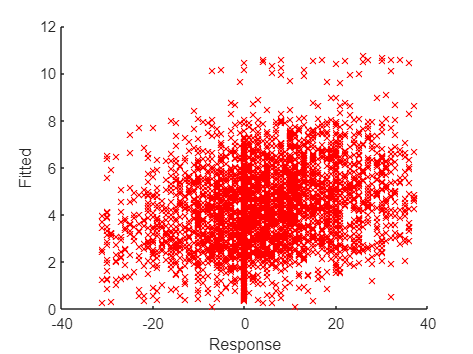

F = fitted(lme12);
R = response(lme12);
figure(); hold on;
plot(R,F,'rx')
xlabel('Response')
ylabel('Fitted')
hold off; 

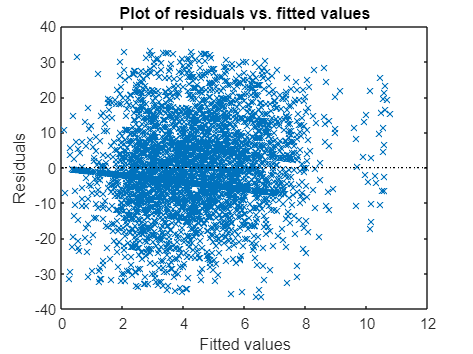


figure();
plotResiduals(lme12, 'fitted')

We see less of an obviuos pattern in these residuals as well. There's an odd line around 0 for both of these right now though. 

Questions:

How can I  verify the model accuracy?

Would trying to make a predictive model for some participants left out be a good next step?

Will this be useful to apply to my patient population by adding in iEEG signal?

This was made after discussion w/ Tor 10/2/23

torlmm = fitlme(master, 'img_rate ~ highcue_indx + Valence_mean + Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx + (highcue_indx + Valence_mean + Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)')

torlmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           6
    Random effects coefficients        834
    Covariance parameters               24

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67288    67498    -33614           67228   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE           tStat       DF      pValue      Lower         Upper    
    {'(Intercept)'                  }             -13.77       19.351    -0.71159    7866     0.47674       -51.703       24.163
    {'highcue_indx_1'              

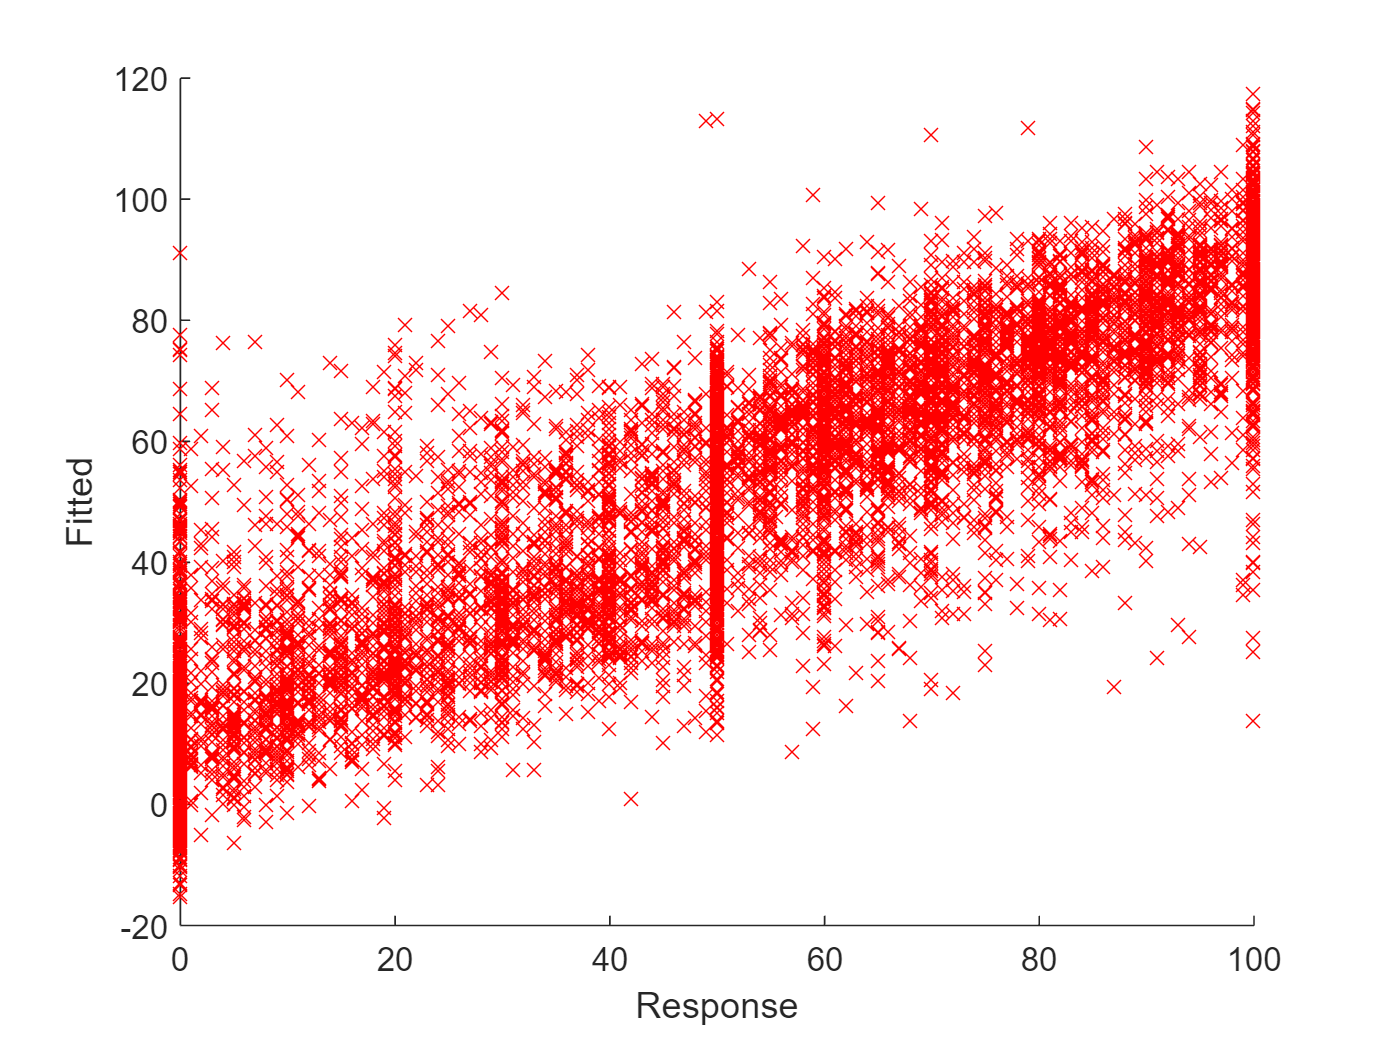

F = fitted(torlmm);
R = response(torlmm);
figure(); hold on;
plot(R,F,'rx')
xlabel('Response')
ylabel('Fitted')
hold off; 

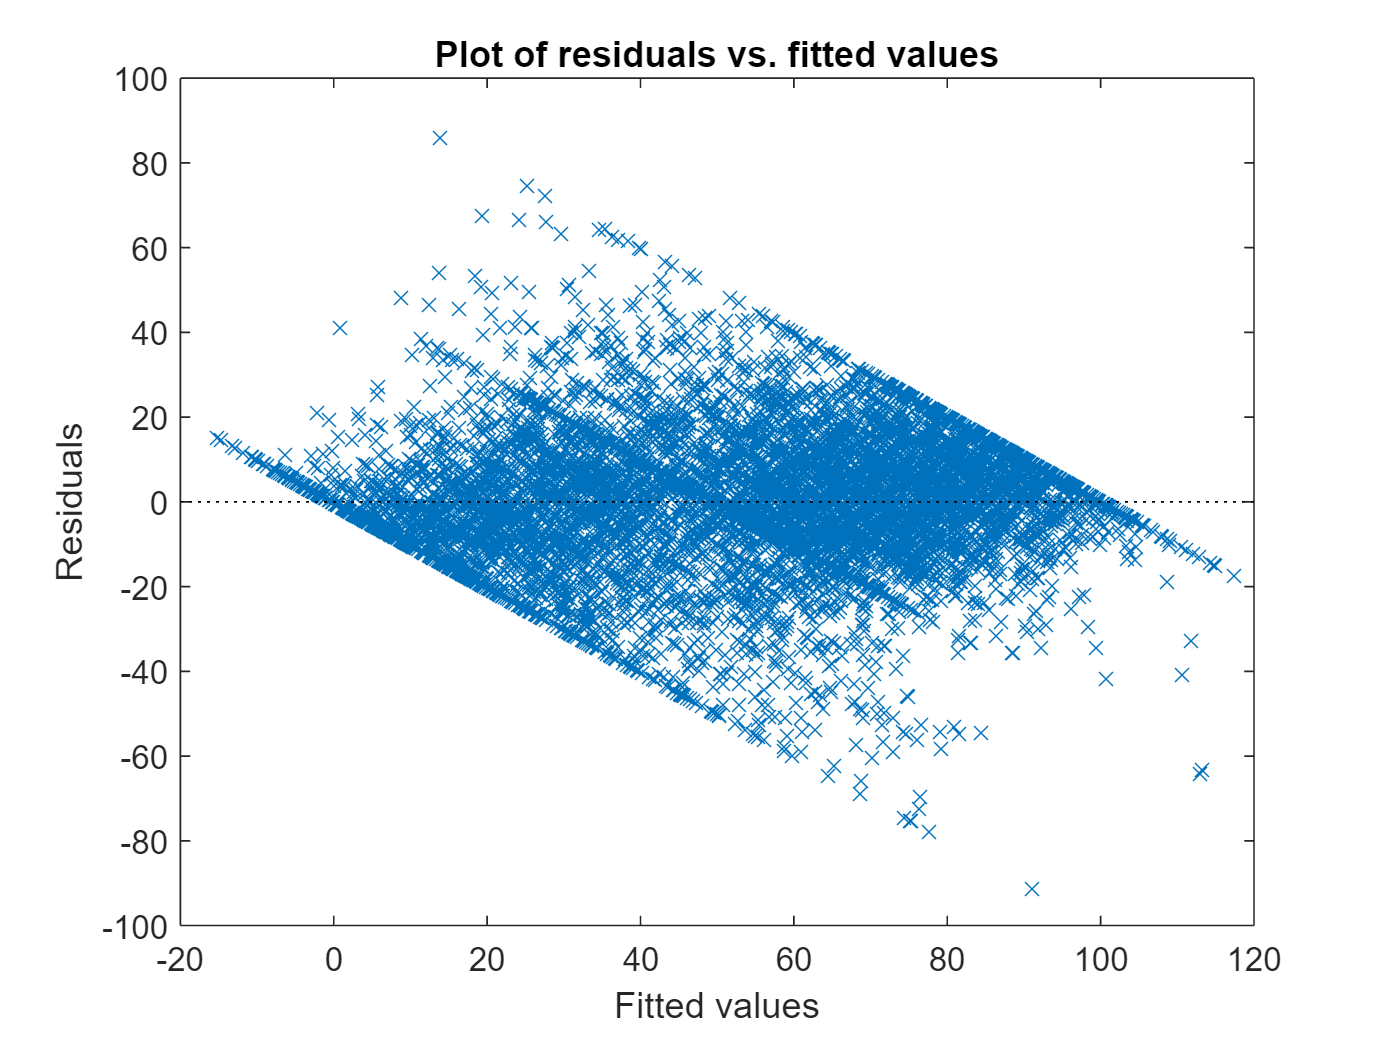



figure();
plotResiduals(torlmm, 'fitted')


lmmfull = fitlme(master, 'img_rate ~ highcue_indx + Valence_mean + Pair*highcue_indx + Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx + (Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)')

lmmfull = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients          68
    Random effects coefficients        834
    Covariance parameters               24

Formula:
    img_rate ~ 1 + highcue_indx*Pair + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67387    68029    -33602           67203   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate     SE          tStat         DF      pValue     Lower        Upper   
    {'(Intercept)'                  }          -14.167      311.83     -0.045433    7804    0.96376      -625.43       597.1
    {'highcue_indx_1' 